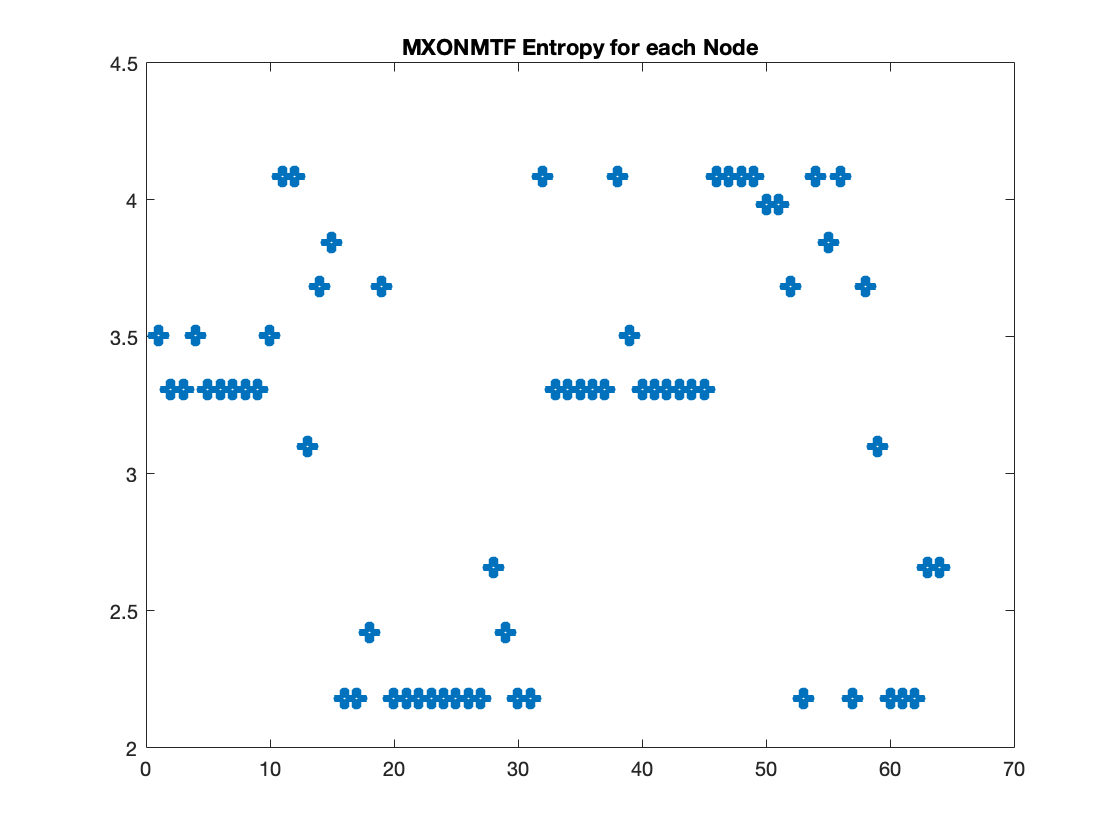

% K communities (common + private ) _> for each node, quantify its
% varibality/consistency across subjects based on community structure ->
% for each node across all subjects generate a length K vector 
% {g_{i}} , each entry will tell you how many times out of 20 subjects node
% i was assigned to community, k -> Normalize this vector to obtain
% probability distribution
% 
%p_{i} = g_{i}/sum_{k}g_{i}(k),p_{i} is a vector K x 1 
% sum((all k that contain i)_g(len(23))
%for each node i is fixed, vary the k , sum of gi across communities
% p_1 = prob of node 1, untill 64
%compute entropy {H(i) = -sum{k}p_{i}(k)log2p_{i}(k)
%generalized louvain algorithm
%use git code multicat: https://github.com/GenLouvain/GenLouvain/blob/master/HelperFunctions/multiaspect.m
%multilayer modularity (categorical coupling)
%undirected layers


load("intercluster_strength_data_A09threshold.mat")

N=64;
L=20;

un_len; %all unqiue clusters private and common
layer_nodes_per_cluster; %is 1xunique clusters cell, each cell, L rows by 64 columns
%if the node is in that cluster in that layer than binary marked as 1

%g -> each entry will tell you how many times out of 20 subjects node i was assigned to community
g = [];
prob = []; %probability distribution

for i=1:64
    g = [g, {zeros(un_len,1)}];
    prob = [prob, {zeros(un_len,1)}];
end


%entropy
%lower entropy ,low variability / high consistency
%high entropy, high variability / low consistency


H = zeros(64,1);

%g = [1,2,3,4,5,6,7,8,9...64]
%g[1] = [1...23] , across all clusters


for cluster=1:un_len
    for layer=1:L
        for node=1:N
            node_temp = layer_nodes_per_cluster{1,cluster}(layer,node);
            g{node}(cluster,1) = g{node}(cluster,1) + node_temp;
        end
    end
end

%p_{i} = g_{i}/sum_{k}g_{i}(k),p_{i} is a vector K x 1 
% sum((all k that contain i)_g(len(23))

for node=1:N
    sum_of_node_in_Ks = sum(g{node});
    for cluster=1:un_len
        prob{node}(cluster,1)= g{node}(cluster,1)/sum_of_node_in_Ks;
    end
end


for node=1:N
    sum_of_prob_in_Ks = 0;
    for cluster=1:un_len
        if prob{node}(cluster,1) ~= 0
            temp = prob{node}(cluster,1)*log2(prob{node}(cluster,1));
            sum_of_prob_in_Ks = sum_of_prob_in_Ks + temp;
        end
    end
    H(node) = -1*sum_of_prob_in_Ks;
end

figure;
plot(H,'o','LineWidth',5)

hold on;
title(sprintf('MXONMTF Entropy for each Node'));     
hold off;

% 
% % Initialize an empty map object
% numMap = containers.Map('KeyType', 'double', 'ValueType', 'any');
% 
% % Example list of numbers
% numList = H';
% 
% % Iterate over each number in the list
% for i = 1:length(numList)
%     num = numList(i);
%     
%     % If the number is already in the map, mark the index
%     if isKey(numMap, num)
%         numMap(num) = [numMap(num), i]; % Use () operator to retrieve value, not as an index
%     % Otherwise, add the number to the map with the index as its value
%     else
%         numMap(num) = i;
%     end
% end
% 
% 
% % Extract the keys and values from the map object
% keys = cell2mat(keys(numMap));
% values = cell2mat(values(numMap));
% 
% % Plot the keys and values on a graph
% figure;
% hold on;
% for i = 1:length(keys)
%     scatter(keys(i), values(i), 'filled', 'SizeData', 100);
% end
% hold off;
% xlabel('Entropy');
% ylabel('Number of Nodes with Entropy');
% 
% title('Number of Occurrences of Entropy');

% 1 topoplot with circles based on entropy
topo_plots = '10-5-System_Mastoids_EGI129.locs';
aij64 = Al{1};    %64 channels
nch = 64; %take care of this variable (nch must be according to matrix size you want to plot it)
ijw = adj2edgeL(triu(aij64));             %passing from matrix form to edge list form
%one issue is Meiby labels weren't working so went back to old EGG labels

n_features = H;
cbtype = 'nocb';

figure;
hold on;
title("Topoplot of Node Entropy");
ax = gca;
ax.TitleFontSizeMultiplier = 3;
   
f_PlotEEG_BrainNetwork(nch, ijw, 'w_unity', n_features, 'n_nn2nx', cbtype);

Nodes scaling is fixed


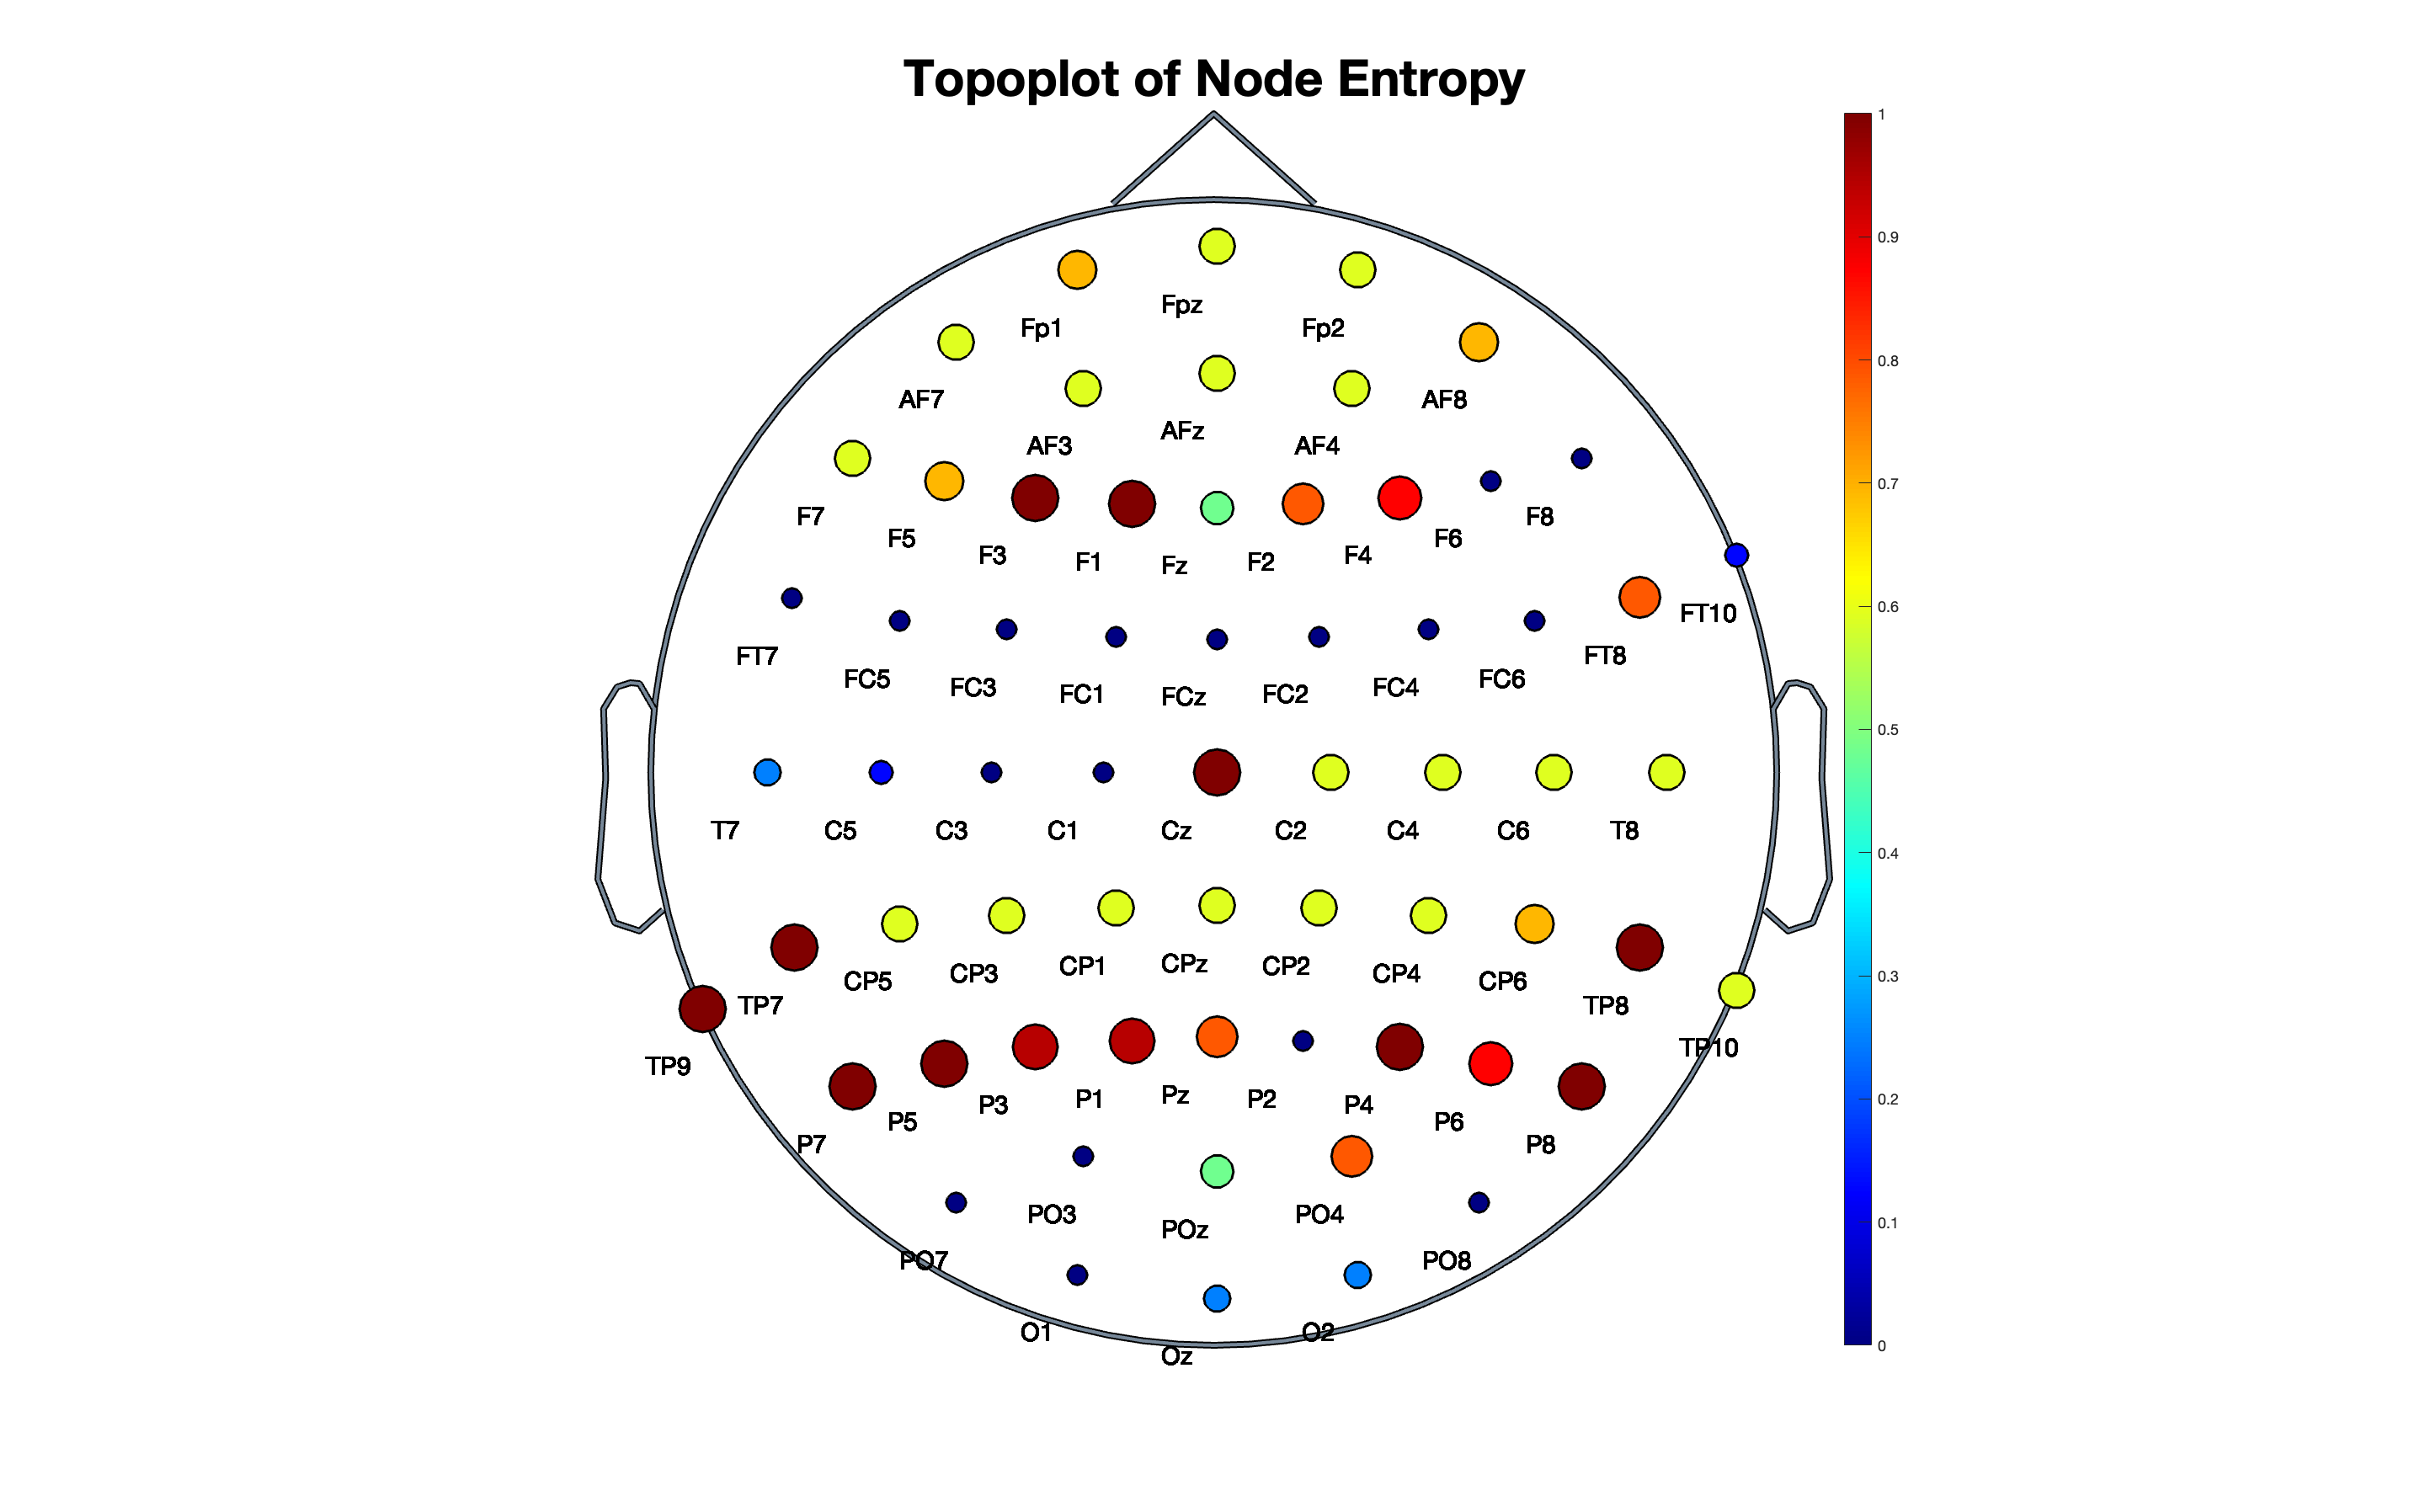

colorbar;
hold off;